## Proyecto: Control de circuito RC

### ** Función de transferencia del modelo de la planta**

Planta `P`

s=tf('s');

% Valores nominales
R1 = 10*10^(3);
R2 = 10*10^(3);
C1 = 100*10^(-6);
C2 = 100*10^(-6);

% Valores experimentales
% R1 = 9.960*10^(3);
% R2 = 9.970*10^(3);
% C1 = 96.2*10^(-6);
% C2 = 95.8*10^(-6);

% Función de transferencia de lazo abierto
P=1/(R1*R2*C1*C2*s^2 + (R1*C1 + R1*C2 + R2*C2)*s + 1);

### Bode de la planta

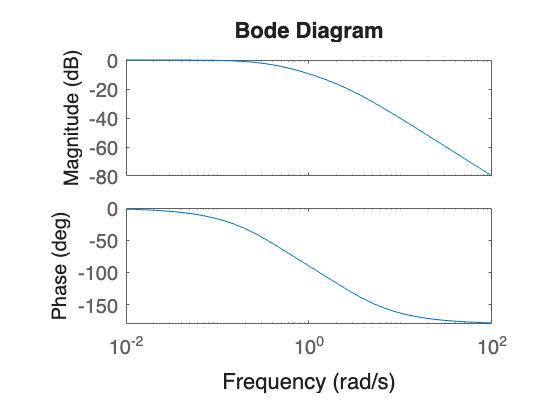

% Bode de lazo abierto
bode(P);

### Respuesta temporal de lazo abierto

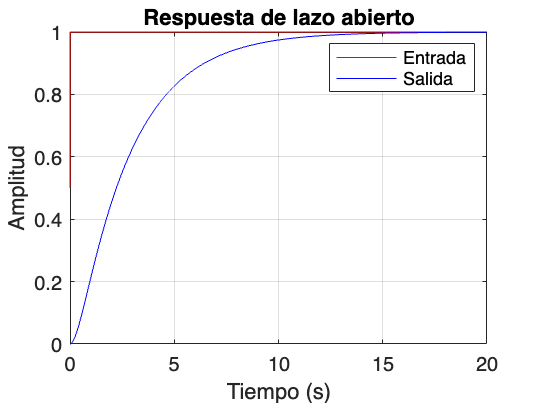

% Tiempo
t = 0:0.001:20;

% Función escalón unitario
u = 1 * heaviside(t);

% Simular el sistema de lazo abierto
y = lsim(P, u, t);

% Graficar
figure
plot(t, u, 'r', t, y, 'b')
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Respuesta de lazo abierto');
legend('Entrada', 'Salida');
grid on;

### `Sisotool`

sisotool(P);

- Se le añade un integrador al controlador para tener un error estacionario 0 ante una entrada de escalón unitario.

- En el LGR se colocan las restricciones de tiempo de asentamiento al 2% (s) y sobrepaso máximo (%). El problema es que dos polos no están dentro del espacio permitido (blanco).

- Según los requerimientos, se necesita que responda en menos de 5 s y un sobrepaso máximo menor al 5%. Se requiere aumentar el tiempo de respuesta, lo cual indica que hay que colocar un cero. Sin embargo, hay que tomar en cuenta que la función de transferencia del controlador debe ser propia (hay que agregar un polo también).

- El polo se colocó en -20, debido a que se busca que este sea al menos 10 veces más grande que el 0.8 (en el eje real). Este corresponde al punto en el eje horizontal dado por la restricción del tiempo se asentamiento. Se busca que el polo no tenga efecto y por eso se coloca alejado.

- Como hay 2 polos (integrador y el anterior), se pueden agregar dos ceros (con un cero no era suficiente para el tiempo de asentamiento). Estos ceros se colocaron muy cercanos a la recta de restricción en -0.8, para que se tenga el comportamiento requerido. Los valores como tal fueron seleccionados mediante un ajuste fino con la respuesta temporal del sistema. 

- Se tiene un tiempo de asentamiento de 0.988 s y un sobrepaso máximo de 0.827%.

### Conversión de continuo a analógico


C_discreto =
 
  277.78 (z^2 - 1.924z + 0.9276)
  ------------------------------
         (z-1) (z-0.1353)
 
Sample time: 0.1 seconds
Discrete-time zero/pole/gain model.
Model Properties


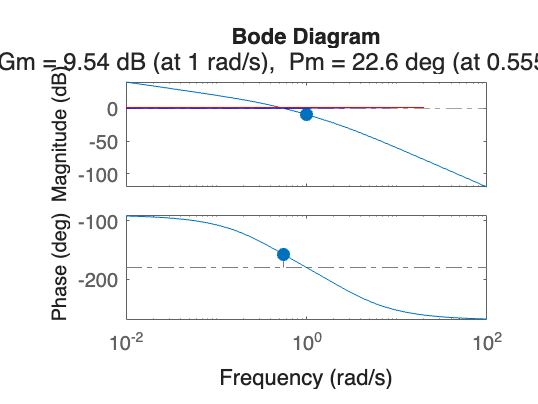

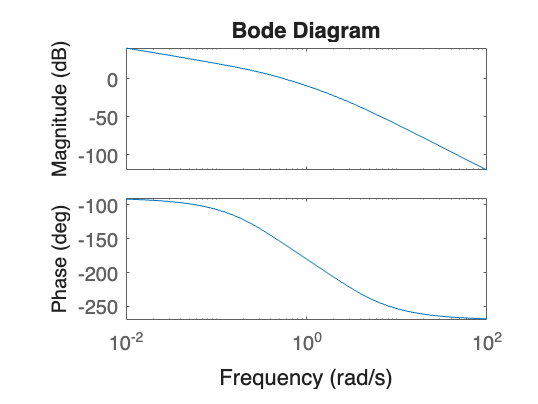


Cad =
 
   2.2 s + 1
  ------------
  0.9859 s + 1
 
Continuous-time transfer function.
Model Properties


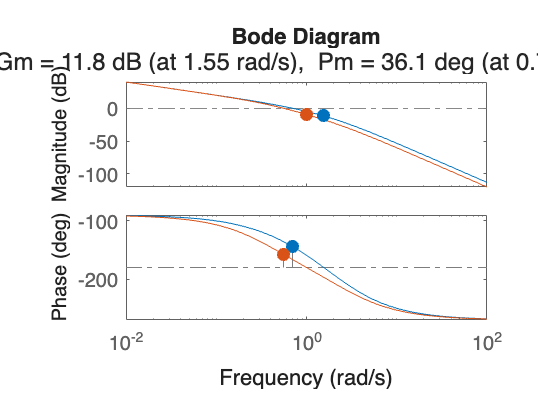

% Convertir controlador a discreto
t_muestreo = 0.1;

C_discreto = c2d(C, t_muestreo, 'zoh')

### LGR

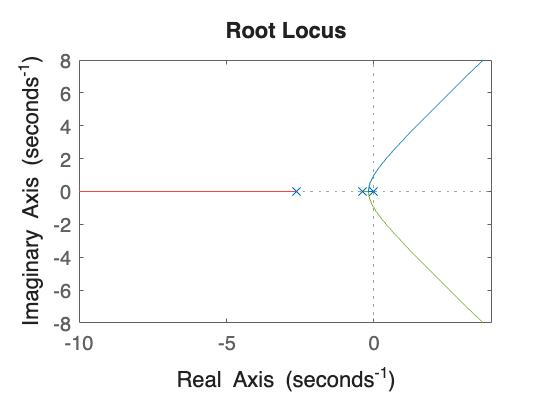

% Indicar los polos
pole(P/s);

figure
% Dibujar LGR
rlocus(P/s);
datacursormode on;

### `Respuesta temporal`

% Ganancia del controlador
Kp = 20;

% Tiempo
t = 0:0.001:10;

% Respuesta de lazo cerrado
Myr = feedback(L * Kp, 1);

% Función escalón unitario
u = 1 * heaviside(t);

% Simular el sistema de lazo cerrado
y = lsim(Myr, u, t);

% Graficar
plot(t, u, 'r', t, y, 'b')
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Respuesta en el dominio del tiempo del sistema con Kp=26.25');
legend('Entrada', 'Salida');
grid on;